addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Interpolation'))

Question 3, part a)

xs = [0 1 2 3 4 5];
ys = [0 0.45 1.06 1.37 2.25 2.47];
poly = interpLagrange(xs, ys)

$$poly = -0.02858333333\,x^{5}+0.34125\,x^{4}-1.409583333\,x^{3}+2.34875\,x^{2}-0.8018333333\,x$$

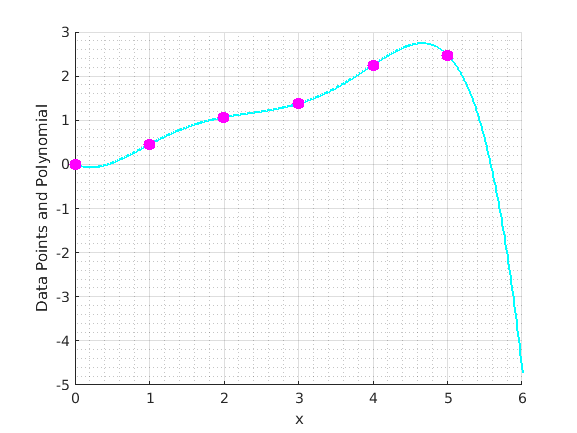

plotPoly(xs, ys, [min(xs), 6], poly)

Question 3, part b)

xs2 = [0 1 2 3 4 5];
ys2 = [0 0.45 1.06 1.73 2.25 2.47];
poly2 = interpLagrange(xs2, ys2)

$$poly2 = 0.001416666667\,x^{5}-0.01875\,x^{4}+0.06041666667\,x^{3}+0.00875\,x^{2}+0.3981666667\,x$$

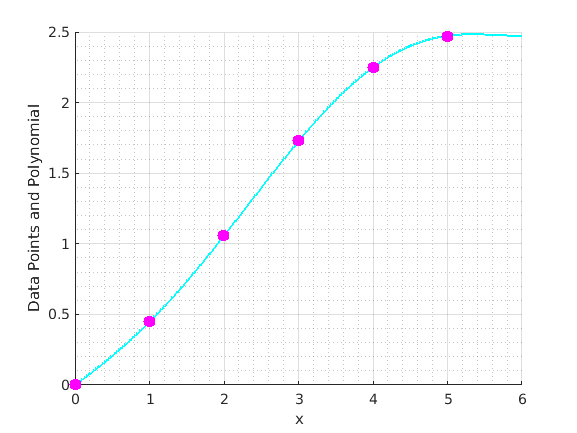

plotPoly(xs2, ys2, [min(xs2), 6], poly2)

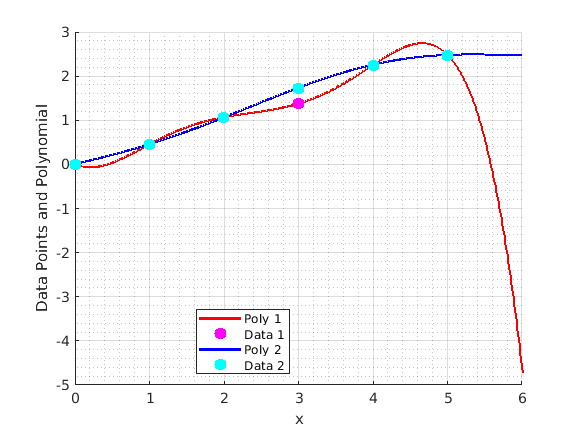

% comparing the plots
plotComparePoly(xs, ys, xs2, ys2, 0, 6, poly, poly2)

%difference between the two estimates at x = 3
calc(poly, 3) - calc(poly2, 3)

$$ans = -0.36000000000000000629460676290772$$

% difference between the two estimates at x = 6 (extrapolation)
calc(poly, 6) - calc(poly2, 6)

$$ans = -7.1999999999999995816497497247433$$